## Robotics System Toolbox I

**Tasks 1-4** are supposed to be solved with the Ubuntu command line and do not need to be submitted.

**5)** Connect with `rosinit(’<YOUR_ROS_MASTER_URI>’)` to the external ROS master. In your case the ROS master resides on the VM ubuntu. You can specify the address of the master in two ways: by an IP address or by a host name of the computer that runs the master.

rosshutdown
rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_44682 with NodeURI http://192.168.2.111:64987/


**6)** The primary mechanism for ROS nodes to exchange data is to send and receive messages. Messages are transmitted on a topic and each topic has a unique name in the ROS network. Ensure that all nodes can communicate with the master and with each other. The individual nodes communicate with the master to register subscribers, publishers, and services. Use `rostopic list` to see which topics are available. Check with `rostopic info` whether the topics `/scan`, `/odom` and `/cmd_vel` are available in the ROS network.

rostopic list

/amcl/parameter_descriptions                                    
/amcl/parameter_updates                                         
/amcl_pose                                                      
/camera/depth/camera_info                                       
/camera/depth/image_raw                                         
/camera/depth/points                                            
/camera/parameter_descriptions                                  
/camera/parameter_updates                                       
/camera/rgb/camera_info                                         
/camera/rgb/image_raw                                           
/camera/rgb/image_raw/compressed                                
/camera/rgb/image_raw/compressed/parameter_descriptions         
/camera/rgb/image_raw/compressed/parameter_updates              
/camera/rgb/image_raw/compressedDepth                           
/camera/rgb/image_raw/compressedDepth/parameter_descriptions    
/camera/rgb/image_raw/com

**7) **Use `rossubscriber` to subscribe to the `/scan` topic. `rossubscriber` detects its message type automatically. Use `receive` to wait for a new message (the second argument is a time-out in seconds). Assign the scan message to `laserMsg` in order to store the message including the laser scan data.

For some message types such as `LaserScan`, Matlab provides convenient visualizers. Visualize the range data for the `LaserScan` message with the function `plot`. The MaximumRange name-value pair specifies the maximum plot range.

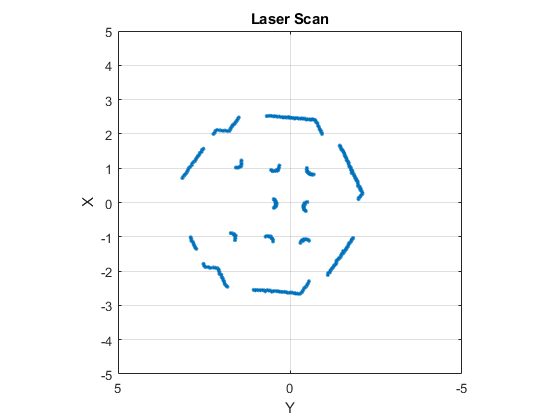

scanSub = rossubscriber('/scan', 'sensor_msgs/LaserScan');
laserMsg = receive(scanSub);
figure;
plot(laserMsg, 'MaximumRange', 5)

**8) **Utilize the subscriber `scanSub` to the /scan topic in an infinite loop that receives and visualizes the scan data at a rate of 5 Hz using a `rate` object.

Superimpose the collected point cloud in a 2D `plot` (using `hold on`) as the robot moves through the environment. The laser scanner moves with the robot and collects range data with respect to the laser frame associated with the robocentric frame. Therefore the point cloud data of consecutive scans is not aligned w.r.t. a static global frame.

The basic infinite loop for receiving and processing messages on a topic is given below.  The while loop terminates once the maxTime elapses.

Loop started, move the robot


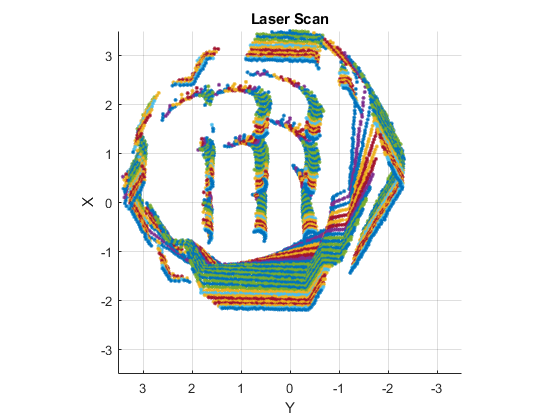

Loop ended


rate = 5; % Rate of 5 Hz
rateObj = robotics.Rate(rate);

goIntoLoop = true; % Switch for activating / deactivating code
if goIntoLoop
    % Prepare Figure
    f1 = figure(1);
    hold on;
    title('Scans in the base link frame');
    
    disp('Loop started, move the robot');
    maxTime = 20;
    rateObj.reset;  % reset time at the beginning of the loop
    while rateObj.TotalElapsedTime < maxTime
        scanMsg = scanSub.LatestMessage;
        plot(scanMsg)
        waitfor(rateObj);
    end
    disp('Loop ended');
end

**9)** Launch the navigation stack for the Turtlebot3 and RViz for visualization with: 

In case you observe an offset between sensor readings and the actual map in RViz, set the inital pose with the `2D Pose Estimate` button in RViz to roughly to the actual position of the Turtlebot3 in the map in Gazebo. In RViz command your robot to navigate to a remote goal location using the `2D NavGoal` button. Run the Matlab script and observe the superposition of laser scan data as the robot moves through the environment.

Paste a screenshot of the matlab figure and the RViz window here.

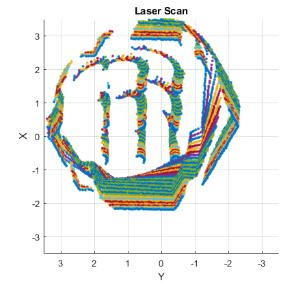       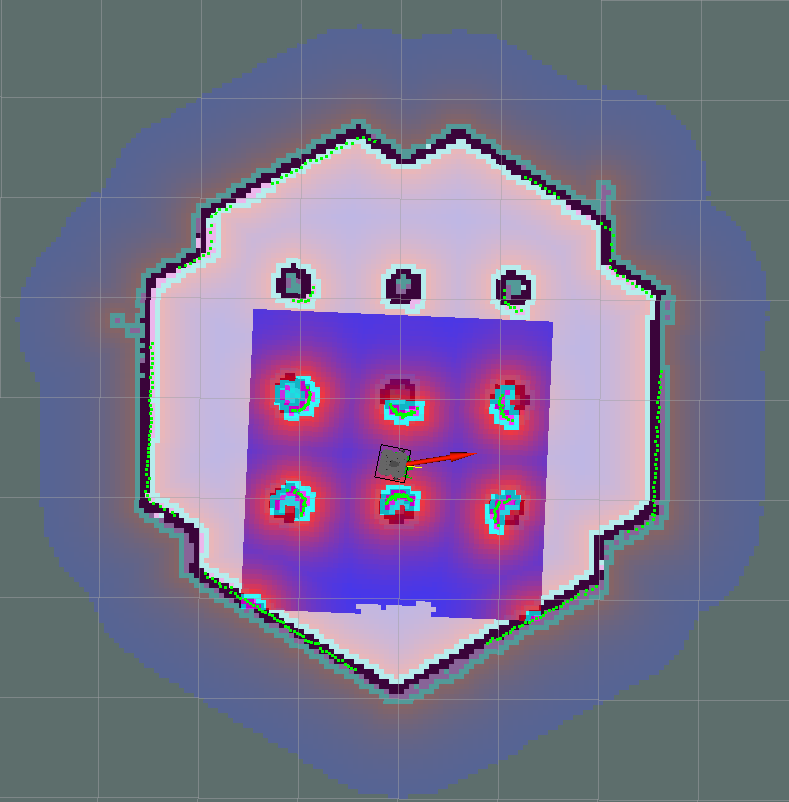

**10)** Create a subscriber odomSub that subscribes to the topic /odom. Obtain the robots current pose.

odomSub = rossubscriber('/odom', 'nav_msgs/Odometry');
odomMsg = odomSub.LatestMessage;
odomMsg.Pose.Pose

ans =   ROS Pose message with properties:

    MessageType: 'geometry_msgs/Pose'
       Position: [1×1 Point]
    Orientation: [1×1 Quaternion]

  Use showdetails to show the contents of the message


**11)** Query the robots current pose with `receive` and inspect the data structure of the `odom` message type in the workspace window, in particular the structure of the `Pose` field and its substructures.

odomMsg = receive(odomSub);
odomMsg

odomMsg =   ROS Odometry message with properties:

     MessageType: 'nav_msgs/Odometry'
          Header: [1×1 Header]
            Pose: [1×1 PoseWithCovariance]
           Twist: [1×1 TwistWithCovariance]
    ChildFrameId: 'base_footprint'

  Use showdetails to show the contents of the message


odomMsg.Pose.showdetails


  Pose          
    Position       
      X :  -0.643934868862196
      Y :  0.04800134322650436
      Z :  -0.001008379828553892
    Orientation    
      X :  0.00123049009426664
      Y :  0.001011205998826132
      Z :  -0.7732945915057704
      W :  0.6340449022778114
  Covariance :  [1e-05, 0, 0, 0, 0, 0, 0, 1e-05, 0, 0, 0, 0, 0, 0, 1000000000000, 0, 0, 0, 0, 0, 0, 1000000000000, 0, 0, 0, 0, 0, 0, 1000000000000, 0, 0, 0, 0, 0, 0, 0.001]


**12)** Utilize the loop and rate object given below. Within the loop receive messages on the `/odom` topic and visualize the robots planar path as a sequence of *x*, *y*-positions in an ordinary plot. For that purpose inspect the structure of the pose message format and extract the *x*, *y*-components of the position part from the field Position.

goIntoLoop = true;
if goIntoLoop
    maxTime = 20; % Maximum loop time (loop terminate after maxTime sec)
    
    % Prepare Figure
    f2 = figure(2);
    clf;
    hold on;
    title('Poses in the odom frame');
    axis([-10 10 -10 10]);
    disp('Odom-Loop started, move the robot');
    rateObj.reset;  % reset time at the beginning of the loop
    while rateObj.TotalElapsedTime < maxTime
        odomMsg = receive(odomSub);
        posex = odomMsg.Pose.Pose.Position.X;
        posey = odomMsg.Pose.Pose.Position.Y;
        
        % (loop continues with code below)

**13) Optional:** The robots orientation is stored as a quaternion in the field `Orientation` of the field `Pose`. The function `quat2eul` converts the quaternion vector [$\eta$, $\epsilon_x$, $\epsilon_y$, $\epsilon_z$] into the Euler angle representation. Extract the current robot orientation $\theta$ of the robot along the *z*-axis in degrees from the first Euler angle. Augment your script such that it plots the robot planar position and orientation at location *x*, *y* with a unit vector in direction [$\cos \left(\theta \right)$, $\sin \left(\theta \right)$] with `quiver. `The function `quiver(x,y,u,v,scale)` has a scale parameter to adjust the size of the vectors in the plot`.`

Odom-Loop started, move the robot


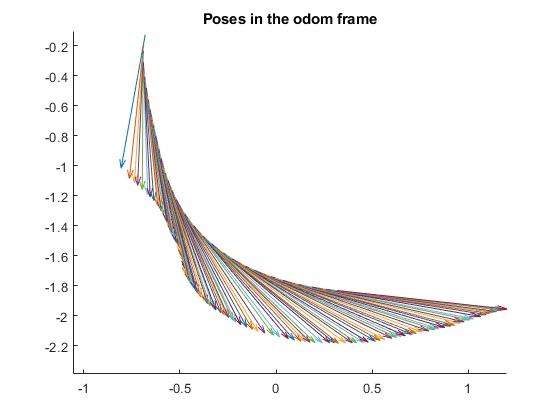

Loop ended


        quat = odomMsg.Pose.Pose.Orientation;
        eulerang = quat2eul([quat.W quat.X quat.Y quat.Z]);
        theta = eulerang(1);
        
        quiver(posex, posey, cos(theta), sin(theta))
        waitfor(rateObj);
    end
    
    disp('Loop ended');
end

**14)** Command your robot with RViz to navigate to a remote goal location with the `2D NavGoal` button. Start your Matlab script and observe the evolution of the robot path in the Matlab figure. 

Paste a screenshot of the Matlab figure and the RViz window here.

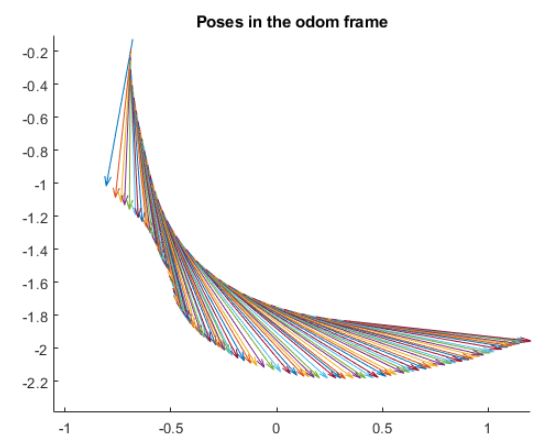   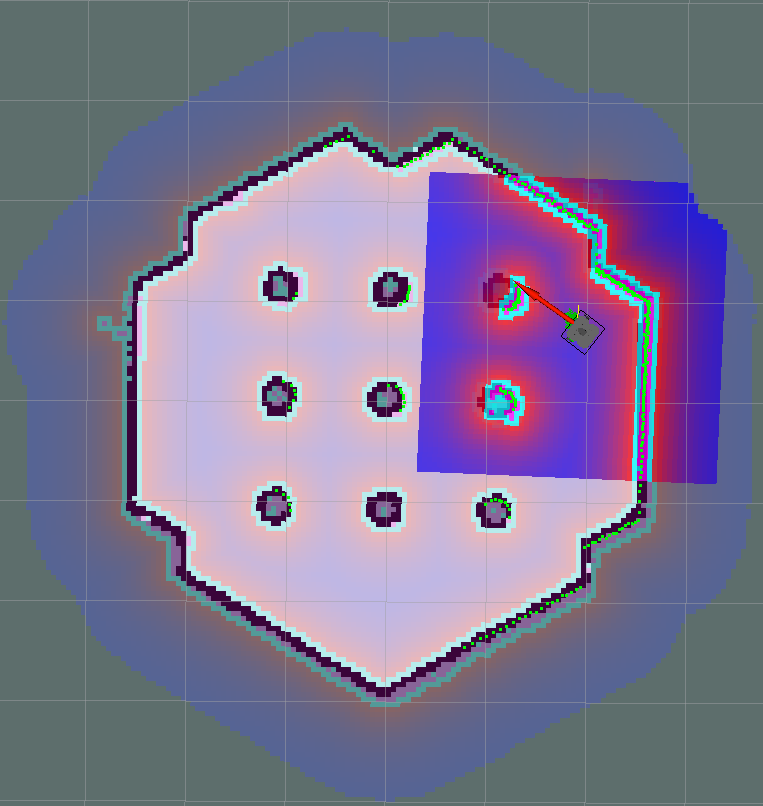

**15)** Implement the following Matlab Function (at the bottom of this script)

**16)** Plot the robot path using a callback function rather than the main loop as before. Implement a callback function for the odom topic (at the bottom of this script)

**17)** Instantiate a callback subscriber `odomSubCallback` that subscribes to the `/odom` topic and refers to your callback function `odomCallback`. Move the robot and observe the evolution of the path. Clear the callback subscriber `odomSubCallback` to stop plotting. Pausing this script might be helpful in order to be able to clear the subscriber.

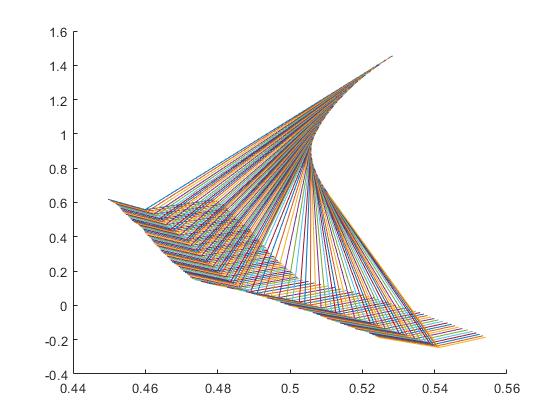

f3 = figure(3);
odomSubCallback = rossubscriber('/odom', {@odomCallback, f3});
pause(10);

clear odomSubCallback;

**18)** Global variables provide a means to share data between the callback function and the workspace of the main program. Declare global variables `xr, yr, thetar` in the main program to denote the robot pose [$x_r$, $y_r$, $\theta_r$] in the world frame.

Declare the same global variables in the callback function odomCallback and assign the pose information extracted from odomMsg. The most current pose information in terms of the global variables can be accessed from the main program. Record pose data within the while loop by storing pose data and current time in arrays. Plot the robot pose components versus time.

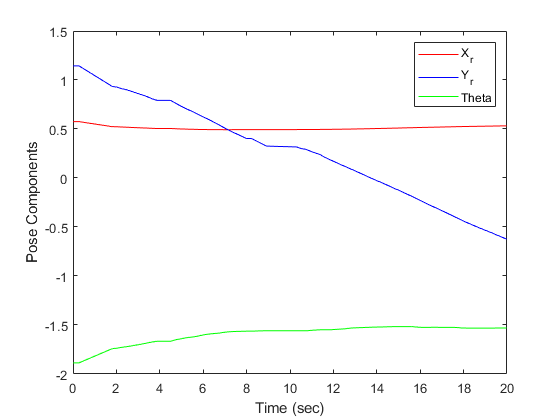

Loop ended


%% Callback subscriber for odom to plot robot path with global variables
global xr yr thetar

goIntoLoop = true;
if goIntoLoop
    maxTime = 20; % Maximum loop time (loop terminate after maxTime sec)
    
    rate = 5; % Rate of 5 Hz
    rateObj = robotics.Rate(rate);
    
    xdata = [];
    ydata = [];
    thetadata = [];
    t = [];
    i = 1;
    clf;
    f4 = figure(4);
    odomSubCallback = rossubscriber('/odom', {@odomCallback, f4});
    rateObj.reset;
    while rateObj.TotalElapsedTime < maxTime
        xdata(i) = xr;
        ydata(i) = yr;
        thetadata(i) = thetar;
        t(i) = rateObj.TotalElapsedTime;
        i = i+1;
        waitfor(rateObj);
    end
    clear odomSubCallback;

    clf;
    plot(t, xdata, 'r'); hold on;
    plot(t, ydata, 'b');
    plot(t, thetadata, 'g'); hold off;
    legend('X_r', 'Y_r', 'Theta');
    xlabel('Time (sec)')
    ylabel('Pose Components')
    disp('Loop ended');
end

**19)** Define a handle class `PoseHandle` with properties `x`, `y`, `theta` to describe the planar robot pose. Select the button `New` in the Matlab Editor menu and select *class* to obtain a template code for class definitions. Provide the class name, the inheritance from the handle class, the property names and their default values. In case of doubt retrieve the file `PoseHandle.m` from the Moodle workspace.

**20)** Augment your callback function `odomCallback` (at the bottom of this script) by an additional input parameter `pose` as a handle object of class `PoseHandle`. Assign the pose information extracted from `odomMsg` to the properties `x`, `y`, `theta` of the pose object.

**21)** In your main program instantiate a handle object `pose` from the class `PoseHandle` and pass it as an additional argument to the callback function `odomCallback` in the instantiation of the `odomSubCallback` subscriber. Replace the assignment to the data recording arrays `xdata`, `ydata`, `thetadata` in the `while` loop from assignment 18). Replace the global variables in the right hand side of the assignment by the corresponding pose properties.

**22)** Augment your callback function by an additional input parameter `fig` to denote the figure in which to plot the robot pose. Notice, that figure objects are already handle objects, that means the `plot` commands in `odomCallback` refer to the original figure object `fig` in the main code.

Instantiate your callback subscriber odomSubCallback with the additional input argument `fig`.

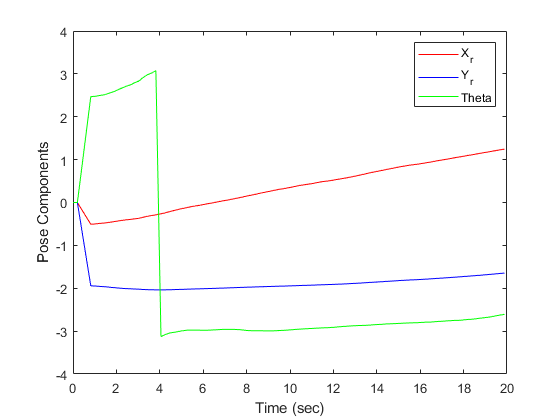

Loop ended



%% Callback subscriber for odom to plot robot path with handle object
pose = PoseHandle;

goIntoLoop = true;
if goIntoLoop
    maxTime = 20; % Maximum loop time (loop terminate after maxTime sec)

    xdata = [];
    ydata = [];
    thetadata = [];
    t = [];
    i = 1;
    clf;
    f5 = figure(5);
    odomSubCallback = rossubscriber('/odom', {@odomCallback, f5, pose});
    rateObj.reset;
    while rateObj.TotalElapsedTime < maxTime
        xdata(i) = pose.x;
        ydata(i) = pose.y;
        thetadata(i) = pose.theta;
        t(i) = rateObj.TotalElapsedTime;
        i = i+1;
        
        waitfor(rateObj);
    end
    clear odomSubCallback;

    clf;
    plot(t, xdata, 'r'); hold on;
    plot(t, ydata, 'b');
    plot(t, thetadata, 'g'); hold off;
    legend('X_r', 'Y_r', 'Theta');
    xlabel('Time (sec)')
    ylabel('Pose Components')
            
    disp('Loop ended');
end

#### Helper Functions

**15) **Write a Matlab function:  

that maps an `odom` message of type `nav_msgs/Odometry` into the components `[x, y, theta]` of the planar robot pose vector. Such a function is convenient for mapping ROS odometry messages into a planar mobile robot pose. The function is provided for future assignments in the Moodle workspace.

function [ x, y, theta ] = OdometryMsg2Pose( odomMsg )
   x = odomMsg.Pose.Pose.Position.X;
   y = odomMsg.Pose.Pose.Position.Y;
   eul = quat2eul([odomMsg.Pose.Pose.Orientation.W odomMsg.Pose.Pose.Orientation.X  odomMsg.Pose.Pose.Orientation.Y odomMsg.Pose.Pose.Orientation.Z]);
   theta = eul(1);
end

**16)** Plot the robot path using a callback function rather than the main loop as before. Write a callback function for the odom topic:

which converts the odomMsg into pose format with OdometryMsg2Pose and plot the pose either as markers (plot) or heading vectors (quiver). 

function [] = odomCallback( ~, odomMsg, fig, varargin)
% Callback function for plotting robot path on topic odom
% fig : figure in which to plot the path
% varargin: use for poseHandle in task 20).
% Use the posehandle if the varargin argument is provided, otherwise use
% the global variables
        global xr yr thetar
        
    if isempty(varargin)
        xr = odomMsg.Pose.Pose.Position.X;
        yr = odomMsg.Pose.Pose.Position.Y;
        eul = quat2eul([odomMsg.Pose.Pose.Orientation.W odomMsg.Pose.Pose.Orientation.X  odomMsg.Pose.Pose.Orientation.Y odomMsg.Pose.Pose.Orientation.Z]);
        thetar = eul(1);   
        hold on;
        figure(fig);
        quiver(xr, yr, cos(thetar), sin(thetar))
    else
        pose_temp = varargin{1};
        %disp(pose_temp);
        [a, b, c] = OdometryMsg2Pose(odomMsg);
        pose_temp.x = a;
        pose_temp.y = b; 
        pose_temp.theta = c;
        hold on;
        figure(fig);
        quiver(a, b, cos(c), sin(c))
    end
        
end